# Positive Real Balanced Truncation and Mixed Gramian Balancing

## Introduction

Balanced Truncation is a well-known reduction method suited for unstructured models. However, the passivity of passive or port-Hamiltonian models is generally not preserved during the reduction. Two adaptations exist that preserve this property: Positive Real Balanced Truncation [1,2] and Mixed Gramian Balancing [1]. 

### The idea

The idea of balancing-based methods is to look for a transformation that brings the system in a balanced representation where states that are less relevant to the transfer behavior can be identified and subsequently truncated. The transformation is chosen based on some physical measurement. Classical Balanced Truncation uses the controllability and observability Gramians to transform the system. These are the solutions to certain Lyapunov equations and are initmiately related to the energy in the system. To preserve passivity of the model the Lur'e equations


$$A^\mathrm{T} X + X A = -L L^\mathrm{T},\\
X B - C^\mathrm{T} = -L W,\\
D + D^\mathrm{T}  = W^\mathrm{T}  W,$$
 

must be fulfilled [1]. This is the case, if at least one solution to an algebraic Riccati equation is used for balancing. In the case of Mixed Gramian Balancing, only one solution is utilized. With two solutions one ends up with Positive Real Balancing. 

### Pseudo-Code

## Toolbox Implementation

The MORpH toolbox provides an implementation of the Positive Real Balancing and Mixed Gramian Balancing algorithms in the function *prbt*.

For more information, refer to the documentation:

help prbt

  prbt - Obtaining a passive reduced order system by positive real
         balancing
  Syntax:
    sysr = prbt(sys)
    sysr = prbt(sys, r)
    sysr = prbt(sys, Opts)
    sysr = prbt(sys, r, Opts)
 
  Description:
        sysr = prbt(sys, r, Opts) returns a passive reduced system with
        given order r by Riccati or mixed Gramian balancing [1].
 
        If r equals the system order, the ssRed object sysr is a balanced
        realization.
 
  Input Arguments:
        *Required Input Arguments:*
        - sys:          sss object, containing passive LTI system
        *Optional Input Arguments:*
        - r:            desired reduced order
        - Opts:  structure with execution parameters
            - .truncation               Define how the model will be truncated
                                        [{'redOrder'} / 'truncTol' / 'userIn' / 'errBound']
            - .redErr                

## Example

The example considered here is a SISO Ladder Network with an architecture as shown below:  

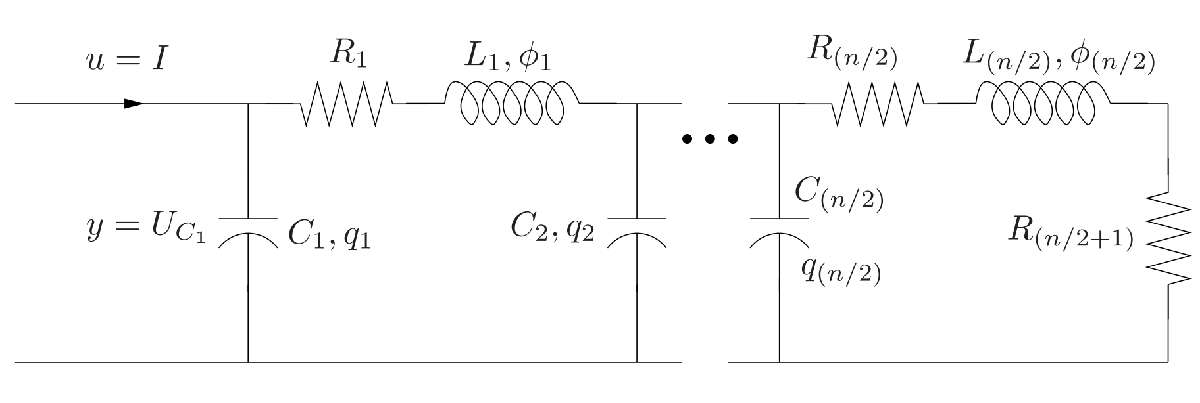

Image source: [3]

We consider a model with dimension $n = 100$, i.e. 50 inductances ($L_i = 0.2\text{H}$), 50 capacitors ($C_i = 0.2\text{F}$) and 51 resistances ($R_i=1\Omega$).

sys = sss(setup_LadderNetworkSystem(100,.2,.2,1))

sys =   (SSS)(SISO)
  100 state variables, 1 inputs, 1 outputs
  Continuous-time state-space model.


*prbt* in its simplest form is called by providing only the original model to reduce and the desired reduced order:

sysr = prbt(sys, 10)

sysr =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10
   x1       -1e-05           5    0.001213    0.003235    0.002616  -0.0003902   -0.002611  -0.0005012  -0.0005854  -9.473e-05
   x2           -5      -5.007      -2.796      -3.816      -2.332      0.2974       1.765      0.3615      0.4173     0.06724
   x3     0.001213       2.796     -0.1626     -0.4817     -0.4203     0.06636      0.4681     0.08721      0.1024      0.0166
   x4     0.003235       3.816     -0.4817      -1.638      -1.621      0.2862       2.284       0.396      0.4706     0.07664
   x5     0.002616       2.332     -0.4203      -1.621      -1.859      0.3912         4.1      0.5985        0.73      0.1201
   x6   -0.0003902     -0.2974     0.06636      0.2862      0.3912     -0.1123      -4.026     -0.2259     -0.3014    -0.05148
   x7     0.002611       1.765     -0.4681      -2.284        -4.1       4.026      -6.885     

norm(sys - sysr)

ans = 0.0029

isPassive(ss(sysr))

ans = logical
   1


### Options

*prbt* option levels are:

- Top level (*prbt*): e.g. balancing scheme 

- Second level (*ss2phs, mess_lrri*): e.g. pH representation 

- Third level (*phs*): e.g. switching on/off input validation

You can find more information on the respective options by having a look at the documentation, e.g.

help ss2phs

  ss2phs - Returns pH system representation of a given passive system
 
  Syntax:
    sysPH = ss2phs(sys)
    sysPH = ss2phs(sys,X)
    sysPH = ss2phs(sys,Opts)
    sysPH = ss2phs(sys,X,Opts)
 
  Description:
        This funciton uses the Kalman-Yakubovic-Popov Lemma to construct a
        port-Hamiltonian system representation of a given passive
        ss object.
 
  Input Arguments:
        *Required Input Arguments:*
        - sys:  ss object to be brought in pH representation
        *Optional Input Arguments:*
        - X: solution to positive real Riccati equation
        - Opts: structure with execution parameters
            - .tol:             If D+D' is not positive definite, D is replaced
                                by Opts.tol*eye(m).
                                [{1e-12} / positive double]
            - .representation:  Defines the pH system representation
                       

To provide these options, use nested structs. As example, the following code changes the balancing scheme and the Lyapunov equation solver:

Opts = struct();
Opts.mixedGramian = 'mixedControl'; % Balancing Scheme
Opts.lyap = 'lyapchol';             % Function to solve Lyapunov equation
Opts

Opts = struct with fields:
    mixedGramian: 'mixedControl'
            lyap: 'lyapchol'



sysr = prbt(sys,10,Opts)

sysr =
 
  A = 
                       x1                 x2                 x3                 x4                 x5                 x6                 x7                 x8
   x1    -0.0399-4.4e-27i   -0.181+3.88e-26i  -0.0788-4.52e-25i   -0.306-5.41e-25i   0.0379-5.69e-26i   0.0728-2.06e-26i   0.0268+3.07e-24i  -0.0403-2.58e-23i
   x2    -0.181-1.33e-25i    -1.07-6.34e-26i   -0.555-3.59e-24i    -3.19-6.91e-24i     0.311+2.3e-24i    0.627+7.23e-26i    0.234+1.82e-23i   -0.356-2.19e-22i
   x3   -0.0788-2.56e-25i   -0.555-4.89e-25i   -0.337-3.93e-24i    -4.13+6.63e-24i     0.231+1.4e-24i    0.505-6.68e-24i    0.194+1.73e-23i   -0.302-1.82e-22i
   x4     0.306-8.14e-25i     3.19-8.66e-24i     4.13+4.61e-24i    -6.66+1.44e-23i     4.12-2.63e-23i     4.18+4.15e-23i     1.35+1.09e-22i    -1.86-1.18e-21i
   x5    0.0379-2.02e-25i    0.311+2.58e-24i    0.231+5.47e-24i    -4.12-6.01e-23i   -0.235+1.31e-23i   -0.673-1.76e-23i     -0.29-1.3e-23i    0.498+3.29e-22i
   x6    0.0728+2.54e-24i     

norm(sys - sysr)

ans = 4.9455e-04

isPassive(ss(sysr))

ans = logical
   1


### Output

*prbt* provides only the reduced system as output. This ssRed object contains additional information which makes the creation more transparent:

sysr.redParam.method       % Method with which the system was created (should be prbt)

ans = 'prbt'

sysr.redParam.params     % Execution parameters (options)

ans = struct with fields:
      mixedGramian: 'mixedControl'
              lyap: 'lyapchol'
    useCholFactors: 0
            makePH: 0
            ss2phs: [1×1 struct]
            redErr: 0.0100
          truncTol: 0.0100
            hsvTol: 1.0000e-15
               phs: [1×1 struct]
        samPassive: [1×1 struct]
               tol: 1.0000e-12
    checkPassivity: 0
               are: 'icare'
        truncation: 'redOrder'
           areOpts: [1×1 struct]
          lyapOpts: [1×1 struct]


## References

[1] K. Unneland, P. Van Dooren, and O. Egeland. A Novel Scheme for Positive Real Balanced Truncation. In 2007 American Control Conference, pages 947–952, 2007.

[2] J. Phillips, L. Daniel, and L. M. Silveira. Guaranteed passive balancing transformations for model order reduction. In Proceedings 2002 Design Automation Conference (IEEE Cat. No.02CH37324), pages 52–57, 2002.

[3] R. V. Polyuga, "Model reduction of port-Hamiltonian systems", PhD thesis, University of Groningen, 2010.

## Copyright

This file is part of [MORpH](https://github.com/MORLab/MORpH) - a MATLAB toolbox to store, analyze, interconnect and reduce large-scale port-Hamiltonian models.

Authors: Maximilian Bonauer    |    E-Mail: [morlab.rt@ed.tum.de](mailto:morlab.rt@ed.tum.de)    |    Website: [www.epc.ed.tum.de/rt](https://www.epc.ed.tum.de/en/rt/home)  

© 2022 Chair of Automatic Control, TUM (see LICENSE.md)